## Load Preprocessed Data

### Event 10

Path = 'D:\Mastersharif\MasterProject\Surprise\Monkey\EEG_complete_dataset_get_from_flash\NewGitHUb\MonkyProject\Auditory\2079-2022-06-08\S01\Mat Data\CleanData\Epoch_event_10.mat'

Path = 'D:\Mastersharif\MasterProject\Surprise\Monkey\EEG_complete_dataset_get_from_flash\NewGitHUb\MonkyProject\Auditory\2079-2022-06-08\S01\Mat Data\CleanData\Epoch_event_10.mat'

Event10 = load(Path)

Event10 = struct with fields:
             data: [8×901×15 double]
             time: [1×901 double]
    triggerValues: [1×200 uint16]


### Event 20

Path = 'D:\Mastersharif\MasterProject\Surprise\Monkey\EEG_complete_dataset_get_from_flash\NewGitHUb\MonkyProject\Auditory\2079-2022-06-08\S01\Mat Data\CleanData\Epoch_event_20.mat'

Path = 'D:\Mastersharif\MasterProject\Surprise\Monkey\EEG_complete_dataset_get_from_flash\NewGitHUb\MonkyProject\Auditory\2079-2022-06-08\S01\Mat Data\CleanData\Epoch_event_20.mat'

Event20 = load(Path)

Event20 = struct with fields:
             data: [8×901×70 double]
             time: [1×901 double]
    triggerValues: [1×200 uint16]


## Calculate mutual information on the ERP singnal

### ERP for Event 20 

ERP = mean(Event20.data,3);
size(ERP);

### Select Channel Pairs and Window Period

ChannelPairs = [[1,8];[2,7];[1,7];[2,8]];
TimeWindow = [[1,200];[100,300];[200,400];[300,500];[400,600];[500,700];[600,800];[700,900]];

### Mutual Information Calculation on ERP time window

MIResults = zeros(size(ChannelPairs,1),size(TimeWindow,1));
for i=1:size(ChannelPairs,1)
    for j=1:size(TimeWindow,1)
        S1 = ERP(ChannelPairs(i,1),TimeWindow(j,1):TimeWindow(j,2));
        S2 = ERP(ChannelPairs(i,2),TimeWindow(j,1):TimeWindow(j,2));
        DS1 = discretize(S1,3);
        DS2 = discretize(S2,3);
        MIResults(i,j) = Mutual_information(DS1,DS2,3,3);
    end
end    

## Visualization

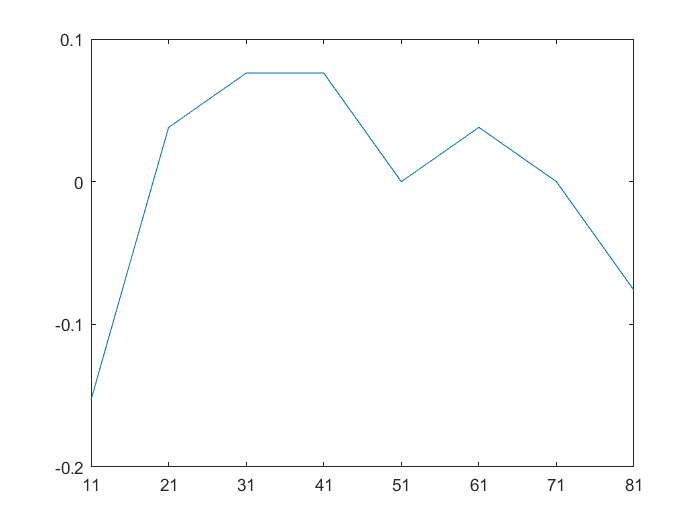

plot(MIResults(4,:))
xticklabels({'11','21','31','41','51','61','71','81','91'})
ylim([-0.2,0.1])